# Usage of AAKR for fault detection

his_T=[1000,1100,900,1050,1000];
his_P=[10,9,8,10,11];
obs_T=1500;
obs_P=10;

Frist, we normalize the data

std_T = std(his_T);
mean_T = mean(his_T);
std_P = std(his_P);
mean_P = mean(his_P);

his_T_nor =(his_T-mean_T)./std_T;
his_P_nor = (his_P-mean_P)./std_P;
obs_T_nor = (obs_T-mean_T)./std_T;
obs_P_nor = (obs_P-mean_P)./std_P;

Then, we then calculate the distance and the weight.

h = 2;
d = (obs_T_nor-his_T_nor).^2+(obs_P_nor-his_P_nor).^2;
w = 1./sqrt(2*pi)./h.*exp(-d.^2./2./h.^2);

After that, we canculate the AAKR value

nc_T=sum(his_T.*w)/sum(w) 

nc_T = 1100

nc_P=sum(his_P.*w)/sum(w) 

nc_P = 9

w/sum(w)

ans =     0.0000    1.0000    0.0000    0.0000    0.0000


Finally we plot it.

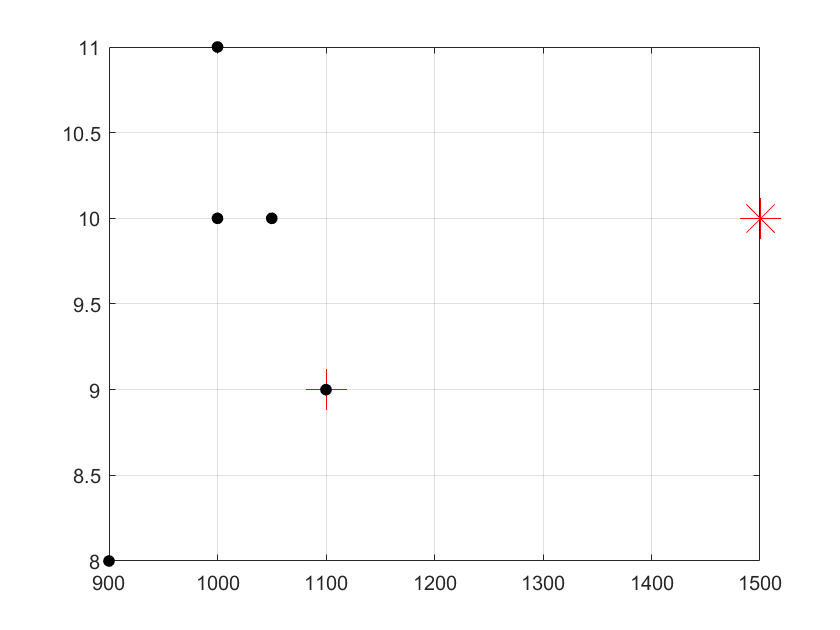

plot(nc_T,nc_P,'r+','MarkerSize', 20);
hold on
plot(his_T,his_P,'k.','MarkerSize', 20);
plot(obs_T,obs_P,'r*','MarkerSize', 20);
grid on;